%YeastDoc modelling tutorial: Excercise #2 
% Exercise2
%
%  - FBA simulations and visualization of results. 
%  - Batch and chemostat simulations
%  
%  based on the latest
%  version of yeastGEM (GitHub: https://github.com/SysBioChalmers/yeast-GEM)
%
% Ivan Domenzain.	Last modified 2019-09-23

## 1. Biomass maximization and exploration of solution structure

%%Save current folder path
current = pwd;
% Load model
load('../models/model_3HP.mat')
% 1) Set the objective function to growth pseudo-reaction
growthRxn = model_3HP.rxns{strcmpi(model_3HP.rxnNames,'growth')};
tempModel = setParam(model_3HP,'obj',growthRxn,1);
% As an alternative way
tempModel.c(:) = 0;
growthIndex    = strcmpi(model_3HP.rxnNames,'growth');
tempModel.c(growthIndex) = 1;
% Take a look into the model's biomass composition
printModel(model_3HP,growthRxn)

FLUXES:
r_2111 (growth)
	biomass[c] =>  [0 1000]


fprintf('\n')

% Set glucose uptake rate
glucIN    = model_3HP.rxns{strcmpi(model_3HP.rxnNames,'D-glucose exchange')};
tempModel = setParam(model_3HP,'lb',glucIN,-1);
% As an alternative way
glucIndex = strcmpi(model_3HP.rxnNames,'D-glucose exchange');
tempModel.lb(glucIndex) = -1;
% run FBA
solution = solveLP(tempModel)

solution = struct with fields:
       x: [3966×1 double]
       f: -0.0880
    stat: 1
     msg: 'Optimal solution found'


% Explore solution structure
colNames        = {'reactions' 'fluxes' 'grRules'};
solution_Fluxes = table(model_3HP.rxnNames,solution.x,model_3HP.grRules,'VariableNames',colNames);

% 2a) Display exchange fluxes
printFluxes(tempModel,solution.x);

EXCHANGE FLUXES:
r_1654	(ammonium exchange):	-0.56076
r_1672	(carbon dioxide exchange):	2.4126
r_1714	(D-glucose exchange):	-1
r_1814	(glycolaldehyde exchange):	5.6831e-06
r_1832	(H+ exchange):	-0.78766
r_1861	(iron(2+) exchange):	-2.7624e-06
r_1992	(oxygen exchange):	-2.2364
r_2005	(phosphate exchange):	-0.02452
r_2020	(potassium exchange):	-0.00031935
r_2049	(sodium exchange):	-0.00034926
r_2060	(sulphate exchange):	-0.00755
r_2100	(water exchange):	3.9202
r_2111	(growth):	0.087974
r_4593	(chloride exchange):	-0.00011349
r_4594	(Cu2(+) exchange):	-5.7975e-05
r_4595	(Mn(2+) exchange):	-0.00024017
r_4596	(Zn(2+) exchange):	-6.5805e-05
r_4597	(Mg(2+) exchange):	-0.00010931
r_4600	(Ca(2+) exchange):	-1.909e-05


fprintf('\n')


% 2b) Display internal fluxes
%%%%%% For this you should take a look into the printFluxes function and
%%%%%% call it accordingly
cutOffFlux = 1E-2;
printFluxes(model_3HP,solution.x,false,cutOffFlux);

FLUXES:
r_0005	(1,3-beta-glucan synthase):	0.06585
r_0006	(1,6-beta-glucan synthase):	0.022002
r_0016	(2-aceto-2-hydroxybutanoate synthase):	0.019473
r_0018	(2-aminoadipate transaminase):	0.028922
r_0020	(2-deoxy-D-arabino-heptulosonate 7-phosphate synthetase):	0.027248
r_0023	(2-isopropylmalate hydratase):	-0.029952
r_0025	(2-isopropylmalate synthase):	0.029952
r_0027	(2-methylcitrate dehydratase):	0.028922
r_0029	(2-oxo-4-methyl-3-carboxypentanoate decarboxylation):	0.029952
r_0039	(3-dehydroquinate dehydratase):	0.027248
r_0040	(3-dehydroquinate synthase):	0.027248
r_0060	(3-isopropylmalate dehydratase):	-0.029952
r_0061	(3-isopropylmalate dehydrogenase):	0.029952
r_0065	(3-phosphoshikimate 1-carboxyvinyltransferase):	0.027248
r_0080	(5,10-methylenetetrahydrofolate reductase (NADPH)):	0.017458
r_0091	(6-phosphogluconolactonase):	0.081177
r_0096	(acetohydroxy acid isomeroreductase):	0.056691
r_0097	(acetolactate synthase):	0.056691
r_0104	(acetyl-CoA C-acetyltransferase):	0.019466
r_

## comparing FBA and pFBA solutions

%3. Run the same simulation using pFBA and repeat steps 2a and 2b, then show 
%the solution vectors as cumulative distribution plots. 
solution_pFBA = solveLP(tempModel,1);
% Explore solution structure
colNames             = {'reactions' 'fluxes' 'grRules'};
solution_pFBA_Fluxes = table(model_3HP.rxnNames,solution_pFBA.x,model_3HP.grRules,'VariableNames',colNames);
% 3a) Display exchange fluxes
printFluxes(model_3HP,solution_pFBA.x);

EXCHANGE FLUXES:
r_1654	(ammonium exchange):	-0.56076
r_1672	(carbon dioxide exchange):	2.4126
r_1714	(D-glucose exchange):	-1
r_1814	(glycolaldehyde exchange):	5.6831e-06
r_1832	(H+ exchange):	-0.024982
r_1861	(iron(2+) exchange):	-2.7624e-06
r_1992	(oxygen exchange):	-2.2364
r_2005	(phosphate exchange):	-0.02452
r_2020	(potassium exchange):	-0.00031935
r_2049	(sodium exchange):	-0.00034926
r_2060	(sulphate exchange):	-0.00755
r_2100	(water exchange):	3.9203
r_2111	(growth):	0.087974
r_4593	(chloride exchange):	-0.00011349
r_4594	(Cu2(+) exchange):	-5.7975e-05
r_4595	(Mn(2+) exchange):	-0.00024017
r_4596	(Zn(2+) exchange):	-6.5805e-05
r_4597	(Mg(2+) exchange):	-0.00010931
r_4600	(Ca(2+) exchange):	-1.909e-05


fprintf('\n')

% 3b) Display internal fluxes
%For this you should take a look into the printFluxes function and
%call it accordingly
cutOffFlux = 1E-2;
printFluxes(model_3HP,solution_pFBA.x,false,cutOffFlux);

FLUXES:
r_0005	(1,3-beta-glucan synthase):	0.06585
r_0006	(1,6-beta-glucan synthase):	0.022002
r_0016	(2-aceto-2-hydroxybutanoate synthase):	0.019473
r_0018	(2-aminoadipate transaminase):	0.028922
r_0020	(2-deoxy-D-arabino-heptulosonate 7-phosphate synthetase):	0.027248
r_0023	(2-isopropylmalate hydratase):	-0.029952
r_0025	(2-isopropylmalate synthase):	0.029952
r_0027	(2-methylcitrate dehydratase):	0.028922
r_0029	(2-oxo-4-methyl-3-carboxypentanoate decarboxylation):	0.029952
r_0039	(3-dehydroquinate dehydratase):	0.027248
r_0040	(3-dehydroquinate synthase):	0.027248
r_0060	(3-isopropylmalate dehydratase):	-0.029952
r_0061	(3-isopropylmalate dehydrogenase):	0.029952
r_0065	(3-phosphoshikimate 1-carboxyvinyltransferase):	0.027248
r_0080	(5,10-methylenetetrahydrofolate reductase (NADPH)):	0.017458
r_0091	(6-phosphogluconolactonase):	0.081266
r_0096	(acetohydroxy acid isomeroreductase):	0.056691
r_0097	(acetolactate synthase):	0.056691
r_0104	(acetyl-CoA C-acetyltransferase):	0.019466
r_

%As you have seen there are many reactions that have -1000 or 1000 flux.
%This is because there are loops in the solution. In order to clean up the
%solution we can minimize the sum of all the fluxes. This is done by
%setting the second argument to solveLP to 1 (take a look at solveLP, there
%are other options as well)

## Visualizing solution vectors as cumulative distributions

%This will show a cumulative distribution of the absolute values of the
%fluxes in the simulation
cd complementary
FluxDist = solution.x(abs(solution.x)>1E-7);
plot2D(abs(FluxDist),[],'FBA simulation','Fluxes value [mmol/gDCW h]','Cumulative distribution',true)

Error using plot
There is no FontSize property on the Line class.

Error in plot2D (line 7)
        plot(x,f,'LineWidth',5,'FontSize',18)

%Look at the new flux cumulative distribution
FluxDist = solution_pFBA.x(abs(solution_pFBA.x)>1E-7);
plot2D(abs(FluxDist),[],'pFBA simulation','Fluxes value [mmol/gDCW h]','Cumulative distribution',true)

## Growth rate vs Glucose uptake rate

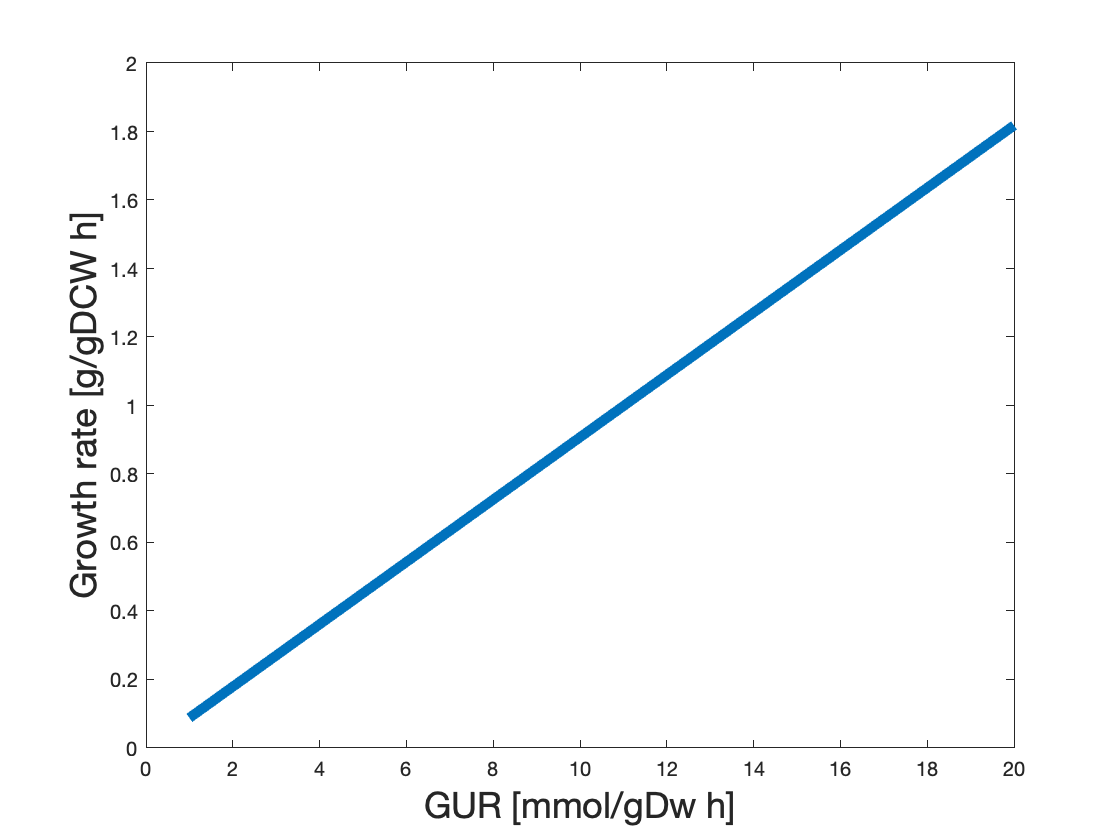

% 5) Plot growth rate vs GUR
gRates  = [];
GURates = [];
for i=1:20+1
    %Set new lb for glucose uptake at every iteration
    GUR = i-1;
    tempModel = setParam(model_3HP,'lb',glucIN,-GUR);
    solution = solveLP(tempModel);
    %If the simulation was feasible then save the results
    if ~isempty(solution.f)
        gRates  = [gRates; solution.x(growthIndex)];
        GURates = [GURates;-solution.x(glucIndex)];
    end
end
%Plot results
plot2D(GURates,gRates,'','GUR [mmol/gDw h]','Growth rate [g/gDCW h]',false)

## Comparing metabolism for growth on two different carbon sources

% 6) Compare flux distributions for growth on glucose and glycerol

% First get the flux distribution on glucose
glyIN         = model_3HP.rxns{strcmpi(model_3HP.rxnNames,'glycerol exchange')};
tempModel     = setParam(model_3HP,'lb',{glucIN glyIN},[-1 0]);
glucIndex     = find(strcmpi(model_3HP.rxns,glucIN));
glycIndex     = find(strcmpi(model_3HP.rxns,glyIN));
grwtIndex     = find(strcmpi(model_3HP.rxns,growthRxn));
solGluc       = solveLP(tempModel,1);
bioYieldGluc  = solGluc.x(grwtIndex)/(solGluc.x(glucIndex)*0.18);
% Get the flux distribution on glycerol
tempModel     = setParam(model_3HP,'lb',{glucIN glyIN},[0 -1]);
solGly        = solveLP(tempModel,1);
bioYieldGlyc  = solGly.x(grwtIndex)/(solGly.x(glycIndex)*0.09209);
%Print results
disp('******************* Growth on Glucose *************************')

******************* Growth on Glucose *************************


printFluxes(tempModel, solGluc.x, true, 10^-6);

EXCHANGE FLUXES:
r_1654	(ammonium exchange):	-0.56076
r_1672	(carbon dioxide exchange):	2.4126
r_1714	(D-glucose exchange):	-1
r_1814	(glycolaldehyde exchange):	5.6831e-06
r_1832	(H+ exchange):	-0.024982
r_1861	(iron(2+) exchange):	-2.7624e-06
r_1992	(oxygen exchange):	-2.2364
r_2005	(phosphate exchange):	-0.02452
r_2020	(potassium exchange):	-0.00031935
r_2049	(sodium exchange):	-0.00034926
r_2060	(sulphate exchange):	-0.00755
r_2100	(water exchange):	3.9203
r_2111	(growth):	0.087974
r_4593	(chloride exchange):	-0.00011349
r_4594	(Cu2(+) exchange):	-5.7975e-05
r_4595	(Mn(2+) exchange):	-0.00024017
r_4596	(Zn(2+) exchange):	-6.5805e-05
r_4597	(Mg(2+) exchange):	-0.00010931
r_4600	(Ca(2+) exchange):	-1.909e-05


fprintf('\n')

disp(['The biomass yield is: ' num2str(bioYieldGluc) ' [g biomass/g Glucose]'])

The biomass yield is: -0.48874 [g biomass/g Glucose]


fprintf('\n')

disp('******************* Growth on Glycerol ************************')

******************* Growth on Glycerol ************************


printFluxes(tempModel, solGly.x, true, 10^-6);

EXCHANGE FLUXES:
r_1654	(ammonium exchange):	-0.29001
r_1672	(carbon dioxide exchange):	1.1447
r_1808	(glycerol exchange):	-1
r_1814	(glycolaldehyde exchange):	2.9391e-06
r_1832	(H+ exchange):	-0.43506
r_1861	(iron(2+) exchange):	-1.4286e-06
r_1992	(oxygen exchange):	-1.5536
r_2005	(phosphate exchange):	-0.9196
r_2020	(potassium exchange):	-0.00016516
r_2049	(sodium exchange):	-0.00018063
r_2060	(sulphate exchange):	-0.0039046
r_2100	(water exchange):	3.3779
r_2111	(growth):	0.045498
r_4527	(diphosphate exchange):	0.45346
r_4593	(chloride exchange):	-5.8692e-05
r_4594	(Cu2(+) exchange):	-2.9983e-05
r_4595	(Mn(2+) exchange):	-0.00012421
r_4596	(Zn(2+) exchange):	-3.4032e-05
r_4597	(Mg(2+) exchange):	-5.6533e-05
r_4600	(Ca(2+) exchange):	-9.873e-06


fprintf('\n')

disp(['The biomass yield is: ' num2str(bioYieldGlyc) ' [g biomass/g Glycerol]'])

The biomass yield is: -0.49406 [g biomass/g Glycerol]


fprintf('\n')

%What if you are interested in how metabolism changes between the two
%conditions. followChanged takes two flux distributions and lets you
%select which reactions to print. Here we show reactions that differ with
%more than 50%, have a flux higher than 0.5 mmol/gDW/h and an absolute
%difference higher than 0.5 mmol/gDW/h.
followChanged(tempModel,solGluc.x,solGly.x, 50, 0.5, 0.5);

These reactions have flux values that differ by more than 50 percent, absolute values above 0.5, and a total difference above 0.5 (31 reactions)

r_0227: ATP[c] + H2O[c] => ADP[c] + H+[e] + phosphate[c]
	ATPase, cytosolic
	Flux: 0 Reference flux: 0.57786 Difference: -0.57786

r_0354: ATP[c] + glycerone[c] => ADP[c] + dihydroxyacetone phosphate[c] + H+[c]
	dihydroxyacetone kinase
	Flux: 0 Reference flux: 1 Difference: -1

r_0445: formate[c] + NAD[c] => carbon dioxide[c] + NADH[c]
	formate dehydrogenase
	Flux: 1.2792 Reference flux: 0.62088 Difference: 0.65828

r_0446: ATP[c] + formate[c] + THF[c] <=> 10-formyl-THF[c] + ADP[c] + phosphate[c]
	formate-tetrahydrofolate ligase
	Flux: -1.2751 Reference flux: -0.61878 Difference: -0.65632

r_0450: D-fructose 1,6-bisphosphate[c] <=> dihydroxyacetone phosphate[c] + glyceraldehyde 3-phosphate[c]
	fructose-bisphosphate aldolase
	Flux: 0.71066 Reference flux: -0.12196 Difference: 0.83262

r_0467: D-glucose 6-phosphate[c] <=> D-fructose 6-phosphate

fprintf('\n')

%Say that we are particularly interested in how ATP metabolism
%changes. Then we can show its related reactions by writing,
followChanged(tempModel,solGluc.x,solGly.x, 30, 0.4, 0.4,{'ATP'});

These reactions have flux values that differ by more than 30 percent, absolute values above 0.4, and a total difference above 0.4 (8 reactions)

Only prints reactions involving one or more of the following metabolites:
ATP 

r_0226: ADP[m] + 3 H+[c] + phosphate[m] => ATP[m] + 2 H+[m] + H2O[m]
	ATP synthase
	Flux: 6.0046 Reference flux: 4.2356 Difference: 1.7691

r_0227: ATP[c] + H2O[c] => ADP[c] + H+[e] + phosphate[c]
	ATPase, cytosolic
	Flux: 0 Reference flux: 0.57786 Difference: -0.57786

r_0354: ATP[c] + glycerone[c] => ADP[c] + dihydroxyacetone phosphate[c] + H+[c]
	dihydroxyacetone kinase
	Flux: 0 Reference flux: 1 Difference: -1

r_0446: ATP[c] + formate[c] + THF[c] <=> 10-formyl-THF[c] + ADP[c] + phosphate[c]
	formate-tetrahydrofolate ligase
	Flux: -1.2751 Reference flux: -0.61878 Difference: -0.65632

r_0534: ATP[c] + D-glucose[c] => ADP[c] + D-glucose 6-phosphate[c] + H+[c]
	hexokinase (D-glucose:ATP)
	Flux: 0.76268 Reference flux: 0 Difference: 0.76268

r_0886: ATP[c] + D-fru

fprintf('\n')

## Exploring production yield for 3HP

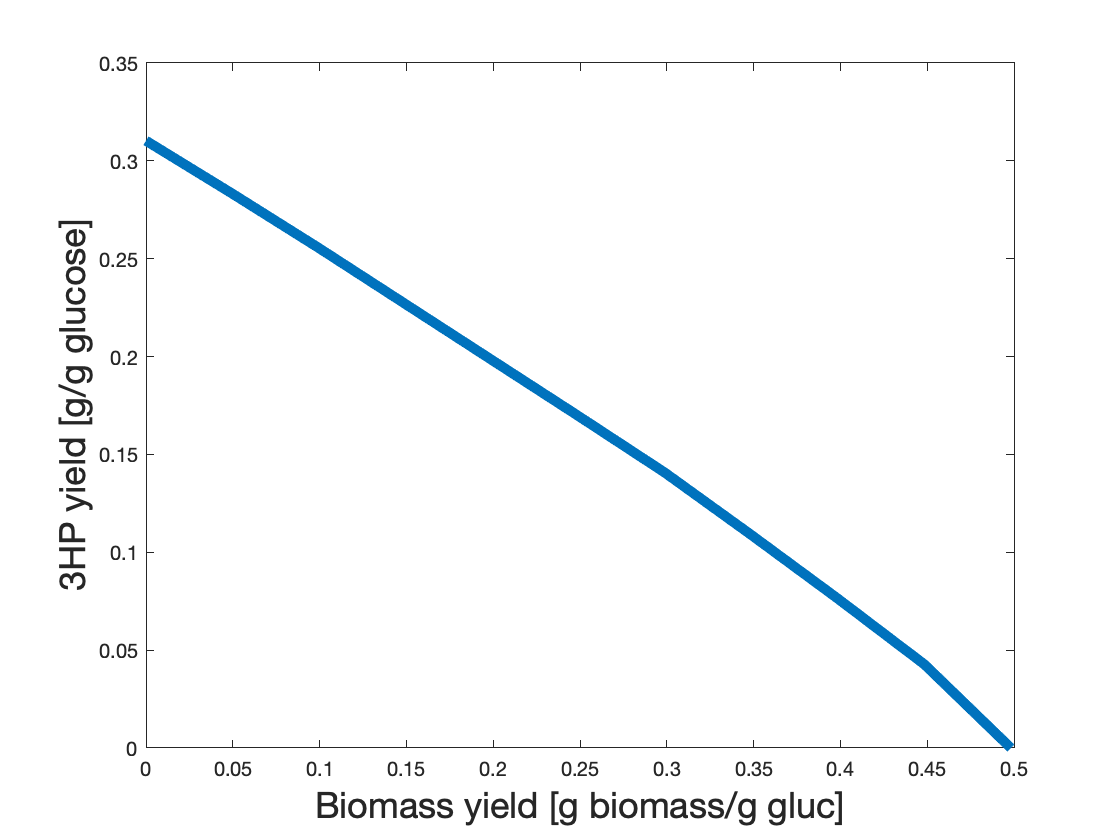

% 7) Get a yield vs gRate plot for 3-Hydroxypropionic acid
BioYield    = [];
yield       = [];
Index3HP    = find(strcmpi(model_3HP.rxnNames,'3HP exchange'));
iterations  = 10;
Dmax        = 0.2;
%Get a maximum GUR
tempModel = setParam(model_3HP,'lb',model_3HP.rxns(growthIndex),0.9999*Drate);
tempModel = minimal_Y6(tempModel,glucIN,-1000);
tempModel = setParam(tempModel,'obj',glucIN,1);
sol       = solveLP(tempModel,1);
GURopt    = sol.x(glucIndex);

for i=1:iterations+1
    % Set the objective function to the added 3HP exchange rxn
    tempModel = setParam(model_3HP,'obj',model_3HP.rxns{Index3HP},1);
    % Set a minimal glucose media (
    tempModel = minimal_Y6(tempModel,glucIN,GURopt);
    % Fix dilution rate at every iteration
    Drate     = Dmax*(i-1)/iterations;
    tempModel = setParam(tempModel,'lb',model_3HP.rxns(growthIndex),0.9999*Drate);
    solution  = solveLP(tempModel);
    if ~isempty(solution.f)
        Exc_3HP  = solution.x(Index3HP);
        % Fix maximal production rate for 3HP
        tempModel = setParam(tempModel,'eq','3HP exchange',Exc_3HP);
        % Fix objective for glucose uptake rate minimization
        tempModel = setParam(tempModel,'obj',glucIN,1);
        solution  = solveLP(tempModel,1);
        GUR       = abs(solution.x(glucIndex));
        % Calculate biomass yield (g biomass/g glucose)
        value     = Drate/(GUR*0.18);
        BioYield  = [BioYield; value];
        % Calculate 3HP yield [mmol 3HP/mmol glucose]
        value     = Exc_3HP*0.0908/(GUR*0.180);
        yield     = [yield; value];
    end
end
plot2D(BioYield,yield,'','Biomass yield [g biomass/g gluc]','3HP yield [g/g glucose]',false)

cd (current)